# Example 3: Design of Experiments using TPMS

This example outlines the process for generating a full factorial design of experiments, by first defining the structure and levels.

## 3.1 Setting up

First, cleanup and set up the paths for data, results and filenames. Also decide what data needs to be calculated and what results we want to save. (Such as saving .stl/.inp/.png/.fig files)

clear variables
close all
warning('off','all');

studyName = "Example-v1"; 
dataPath = 'data\';

% Warning turn these options off if generating a large number of designs
plotFigures = 0; 
saveFigures = 0; 
saveSTL = 0;
calculatemechanical = 0;
calculateSurfMesh = 1;
curvaturemethod = 'none';

if saveFigures||saveSTL
    resultPath = "results\"+studyName+"\";
    if ~isfolder("results\"+studyName)
        mkdir("results\",studyName);
    end
    addpath(resultPath);
end

## 3.2 Define design parameters and levels

Here the variables which parametrically describe the TPMS-like structure are defined.

The **equation** of the tpms, **type** of structure, nodes per unit cell edge (**res**), and isovalues (**v**) define the fundamental structure form and discretisation. 

Alternatively the user my specify a target volume fraction (**vf**) in palce of the primary isovalue (**v1**).

DOE.res = 30; % Resolution (nodes per cell)
DOE.v1 = 0.1:0.1:0.9; % Primary isovalue/(target volume fraction)
DOE.v2 = 0; % Secondary isovalue
DOE.equation = ["Gyroid", "Diamond"];% "Gyroid","Diamond","Primitive", "Neovius", "IWP", "FRD"
DOE.type = ["network", "surface"];% "single","network","double","surface"

A set of parametric affine transformations are defined using Cell Size (L) in mm, Offsets or phase shift (Bx,By,Bz) in mm, and euler rotations (Rx,Ry,Rz) in degrees.

DOE.L = 30; % Cell size (mm)
DOE.nx = 1; %DOE.ny = 1; DOE.nz = 1; % Define number of cells
DOE.Bx = 0; DOE.By = 0; DOE.Bz = 0; % Offsets: x,y,z
DOE.Rx = 0; DOE.Ry = 0; DOE.Rz = 0; % Rotations: pitch,roll,yaw (deg)

## 3.3 Generate the DOE

Next we need to automatically set up the full-factorial design of experiments, including sample names.

Note that any values not set will default to a generally "safe" value when generating the structures.

names = string(fieldnames(DOE));
levels = zeros(length(names),1);
for i = 1:length(names)
    levels(i) = length(DOE.(names(i)));
end

doeFF = fullfact(levels);
doeArray = struct();

for i = 1:size(doeFF,1)
    for j = 1:size(names,1)
        doeArray(i,1).(names(j)) = DOE.(names(j))(doeFF(i,j));
    end
    % Create a name for the sample - you may wish to change this to show
    % more data
    doeArray(i,1).name = studyName+" "+num2str(i,'%4.0f');
end

## 3.4 Run the analysis

Set up the for loop to run each design. You may want to specify the level of analysis - (remembering mechanical, curvature, SurfMesh will all add computational cost and time to every model).

Structure 001 of 036 completed. Elapsed Time: 0.109 seconds


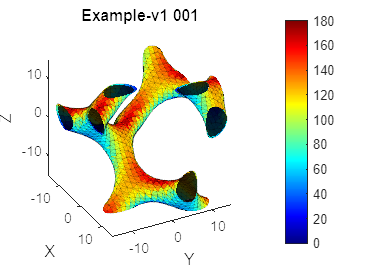

Structure 002 of 036 completed. Elapsed Time: 0.953 seconds
Structure 003 of 036 completed. Elapsed Time: 1.062 seconds
Structure 004 of 036 completed. Elapsed Time: 1.188 seconds
Structure 005 of 036 completed. Elapsed Time: 1.344 seconds
Structure 006 of 036 completed. Elapsed Time: 1.516 seconds
Structure 007 of 036 completed. Elapsed Time: 1.594 seconds
Structure 008 of 036 completed. Elapsed Time: 1.734 seconds
Structure 009 of 036 completed. Elapsed Time: 1.828 seconds
Structure 010 of 036 completed. Elapsed Time: 1.906 seconds
Structure 011 of 036 completed. Elapsed Time: 2.031 seconds
Structure 012 of 036 completed. Elapsed Time: 2.172 seconds
Structure 013 of 036 completed. Elapsed Time: 2.312 seconds
Structure 014 of 036 completed. Elapsed Time: 2.391 seconds
Structure 015 of 036 completed. Elapsed Time: 2.469 seconds
Structure 016 of 036 completed. Elapsed Time: 2.578 seconds
Structure 017 of 036 completed. Elapsed Time: 2.688 seconds
Structure 018 of 036 completed. Elapsed 

starttime = cputime;
for i = 1:size(doeArray,1)
    d = doeArray(i);
    TFORM = simtform3d(d.L,[d.Rx d.Ry d.Rz],[d.Bx d.By d.Bz]); 
    VOLUME = bulkSize('box',d.L.*[d.nx d.nx d.nx]); % Set to one unit cell in each direction 
    VOXSIZE = d.L/d.res; % Maintain consistant 30 nodes per unit cell
    TPMS = UnitCell(d.type,d.equation,d.v1,d.v2,VOXSIZE,TFORM,VOLUME);    %UnitCell = UnitCell(type,equation,v1,v2,res,tform,B)
    % Run full analysis - select (fields,mechanical,SurfMesh,curvature)
    TPMS = TPMS.compute(curvaturemethod,calculatemechanical,calculateSurfMesh);
    % Export the metrics results and display the computational time
    DOEout(i,:) = [table(d.name) struct2table(TPMS.export,'AsArray',true)];
    Message = sprintf('Structure %03.f of %03.f completed. Elapsed Time: %.3f seconds',i,size(doeArray,1),cputime-starttime);
    disp(Message);

    % Preview the structure and save figures
    if saveFigures||plotFigures||i==1
        TPMS.plot("SurfMesh");
        f1 = gcf; ax = gca;
        str = studyName+sprintf(" %03.f",i);
        title(ax,str);
        c=colorbar(ax);
        clim(ax,[0 180]);
        drawnow();
        % Save figures as .png files in the results folder
        if saveFigures
            fid = strcat(resultPath,str,".png");
            saveas(f1,fid,'png');
            delete(f1);
        end
    end

    % Save mesh as .stl files in the results folder
    if saveSTL
        fid = strcat(resultPath,d.name,".stl");
        TPMS.FV.exportSTL(fid);
    end
end

## 3.5 Post processing & Analysis

Below are some examples of data analysis which can be applied to the saved figures and data (DOEout).

**Preview the saved figures to visualise the changes to the design (requires saveFigures = 1)**

if saveFigures
    files = dir(resultPath);
    clear figureFrames
    for i = 3:length(files)
        temp = imread(files(i).name);
        frame = imresize(temp,[420 NaN]);
        figureFrames(:,:,:,i-2) = frame;
    end
    mov = immovie(figureFrames);
    f2 = figure; movie(f2,mov);
end

**Plot variables./properties to plot as X vs Y scatterplots (With grouping of series if applicable)**

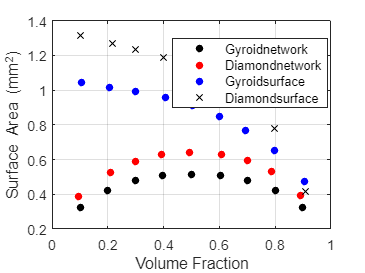

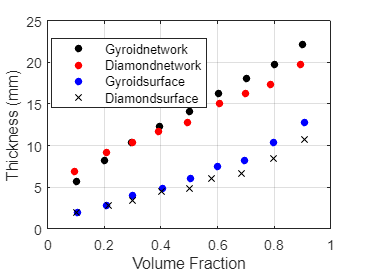

Yvars = ["relativeArea", "thickness"];
plotlabels = ["Surface Area (mm^2)", "Thickness (mm)"];
Xvar = "relativeVolume";
grouping = strcat(DOEout.equation, DOEout.type);
% Set the datapoint colors and symbols
colors = [0 0 0; 1 0 0; 0 0 1;0 0 0; 1 0 0; 0 0 1];
sym = '...xxx';

%Make the plots
for i=1:length(Yvars)
    figure;
    ax = gca;
    L = gscatter(ax,DOEout.(Xvar),DOEout.(Yvars(i)),grouping,colors,sym);
    hold on;
    xlabel('Volume Fraction');
    ylabel(plotlabels(i));
    grid on;
end

**Create main effects plots to explore relationships between output metrics and input variables.**

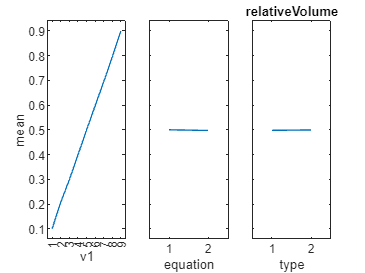

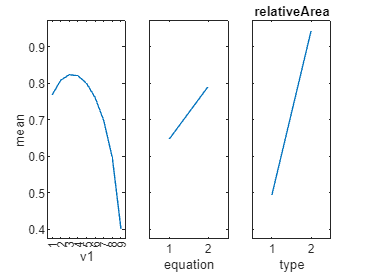

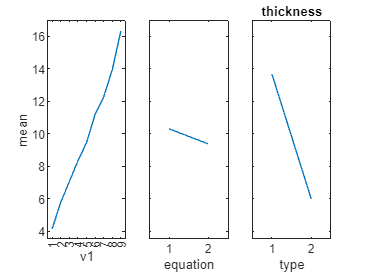

Yvars = ["relativeVolume","relativeArea","thickness"];

for i = 1:length(Yvars)
    figure('Name',Yvars(i));
    maineffectsplot(DOEout.(Yvars(i)),doeFF(:,levels>1),'varnames',names(levels>1,:));
    a = gca;
    title(a,Yvars(i));
end

**Plot results matrix to analyse data distributions.**

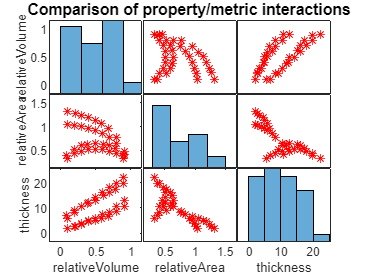

% Conduct an investigation of relationships between ANY input and/or output values using a plot-matrix
figure()
Yvars = ["relativeVolume" "relativeArea" "thickness"];
[S,AX,BigAx,H,HAx] = plotmatrix(table2array(DOEout(:,Yvars)),'*r');
title(BigAx,'Comparison of property/metric interactions');

% Add axis labels
for i=1:length(Yvars)
    ylabel(AX(i,1),Yvars(i));
    xlabel(AX(length(Yvars),i),Yvars(i));
end